# Example 4: Field Case Study at the Dogger Geothermal Reservoir in the Paris Basin (France) - Part I

## Introduction

This is another demonstration problem from reference [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)]. This example serves as a practical demonstration of the Double Delineation Approach (DDA) applied to well doublets within a deep geothermal reservoir. Located in the eastern part of the Paris Basin (Meaux well field), this study area features a Dogger aquifer at depths of 1800 to 2000 meters, where water at 75 °C is extracted and subsequently re-injected at a cooled temperature of 40 °C into the surrounding carbonate formation. The well field comprises four injection-production well doublets, denoted as I1 to I4 for injectors and P1 to P4 for producers. The doublet wells operate at consistent flow rates, with I2-P2 set at ±70 m³/h and the remaining doublets at ±85 m³/h. 

In this example, we will address specific questions regarding the interactions between the injection and production wells, particularly focusing on the identification of well catchments and the characterization of time-related capture zones. We will demonstrate how the DDA facilitates the analysis of these interactions, providing insights that are not easily attainable through conventional particle tracking methods. Through these analyses, we aim to enhance our understanding of the hydraulic dynamics at play within the geothermal reservoir.

We start by clearing all variables from the workspace to ensure a clean environment. Next, we load the necessary units for length and time constants.

clear;                              
setLengthUnitsInWorkspace();        
setTimeUnitsInWorkspace(2024);

## Set up Simulation Data

We define a computational domain that measures 10 kilometers in length, 11 kilometers in width, and 20 meters deep. To facilitate our analysis, we will create a uniform grid consisting of 500 x 550 x 1 cells, with each cell having a size of 20 meters in all directions. 

% Create a grid 
Grid = cartGrid(0:20:10000, 0:20:11000, [0 20]);

We assign a constant hydraulic conductivity value of 6.38e-5 throughout the aquifer.

Grid.properties.hydraulic_conductivity = 6.38e-5 * ones(3, Grid.Nx, Grid.Ny, Grid.Nz);

The porosity is uniformly set at 20%.  

Grid.properties.porosity = 0.2*ones(Grid.Nx,Grid.Ny,Grid.Nz);

Next, we create a two-dimensional grid representation for planar visualization tasks.

G2D = cartGrid(0:20:10000, 0:20:11000);

Set the pumping and injection flow rates.

Q2 = 70 * meter^3/hour;  % flow rate in I2/P2 doublet
Q1 = 85 * meter^3/hour;  % flow rate in all other doublets


Add four injection wells to the model.

W = verticalWell([], Grid, 160, 364, 1, Q1, 'type', 'injection', 'name', 'I1', 'radius', 0.15);
W = verticalWell(W, Grid, 202, 162, 1, Q2, 'type', 'injection', 'name', 'I2', 'radius', 0.15);
W = verticalWell(W, Grid, 240, 249, 1, Q1, 'type', 'injection', 'name', 'I3', 'radius', 0.15);
W = verticalWell(W, Grid, 346, 259, 1, Q1, 'type', 'injection', 'name', 'I4', 'radius', 0.15);

Add four production wells to the model.

W = verticalWell(W, Grid, 208, 342, 1, Q1, 'type', 'pumping', 'name', 'P1', 'radius', 0.15);
W = verticalWell(W, Grid, 216, 206, 1, Q2, 'type', 'pumping', 'name', 'P2', 'radius', 0.15);
W = verticalWell(W, Grid, 295, 229, 1, Q1, 'type', 'pumping', 'name', 'P3', 'radius', 0.15);
W = verticalWell(W, Grid, 287, 289, 1, Q1, 'type', 'pumping', 'name', 'P4', 'radius', 0.15);

% Define well coordinates in terms of grid indices (same as before)
well_coords.xinj = [160, 202, 240, 346];
well_coords.yinj = [364, 162, 249, 259];
well_coords.xpmp = [208, 216, 295, 287];
well_coords.ypmp = [342, 206, 229, 289];

% ...
coord_wx = @(i) (i-1)*Grid.hx + Grid.hx/2;
coord_wy = @(j) (j-1)*Grid.hy + Grid.hy/2;

xinj = coord_wx(well_coords.xinj); 
yinj = coord_wy(well_coords.yinj);
xpmp = coord_wx(well_coords.xpmp);
ypmp = coord_wy(well_coords.ypmp);

## Simulate Steady-State Groundwater Flow and Plot Results 

Simulate the hydraulic heads in the aquifer in response to disturbances from the pumping and injection wells. Assuming the hydraulic head levels stabilize quickly, we will run the simulation using a steady-state model.

tic 
[h,V] = head(Grid, W);

Number of PCG iterations = 51
Residual norm error      = 7.78412E-07


toc

Elapsed time is 0.875377 seconds.


We will now plot the hydraulic head map, highlighting selected equipotential lines. Next, we will release a constant number of particles in the reverse flow direction from circular positions centered around each pumping well.

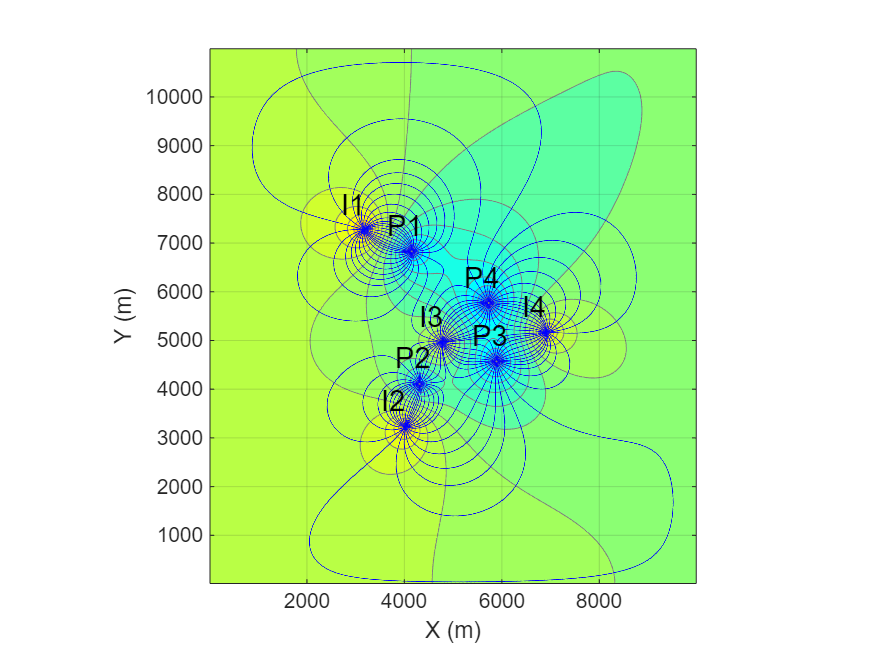

figure; 
opts.fill = 'on';

%--- Plot equipotential lines.
colormap(jet(41));
plotContourData(G2D, h(:), opts, ... 
    'LevelList',round(min(h(:))):1:round(max(h(:))), ...
    'Color',rgb(Color,'gray'), ...
    'LineWidth', 0.5);
hold on;

%--- Calculate and plot all streamlines 
coords = getPointsWithinRadius([xpmp' ypmp'], 20, 30); % get initial positions of particles
plotStreamline(V, [Grid.hx Grid.hy], coords, false, 'Color', 'b', 'LineWidth', 0.5);

%--- Plot customization commands 
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
axis tight equal; 
xlabel('X (m)'); 
ylabel('Y (m)');
grid on
hold off;

The plot displays the flow nets generated by the well doublets, indicating hydraulic interactions between them. Notably, some streamlines connect I1 and P4, suggesting that a portion of the injection flow rate from well I1 is being extracted by well P4.

Studying these hydraulic interactions is crucial for many groundwater assessment studies. The case study involving well doublet design in a low-enthalpy geothermal reservoir is just one example among many others. 

While the particle tracking technique is a valuable approach for highlighting the occurrence of these interactions, it primarily serves as a qualitative tool. Several important questions arise that require a more quantitative analysis, such as: 

- What is the pore volume or area of the aquifer over which any pumping well interacts with an injection well?

- Can we quantify the volume of this area?

- In a complex flow field like this, how is the flow rate at any injection well partitioned among all the pumping wells, and vice versa? 

These are situations where the Double Delineation Approach proves useful, as it allows us to perform these analyses with minimal computational overhead. The method involves conducting a dual delineation of the catchments for injection and pumping wells, utilizing similar equations as those used for dual travel time simulations, as explained in previous examples. Let’s continue and explore how this method works.

## Simulate Pumping Wells Catchments

Now, we will simulate the catchments for all pumping wells. A well catchment refers to the groundwater zone that contributes to a pumping well, defined by the steady-state conditions and the potential aquifer zone from which water is abstracted over time. We employ a numerical method that is a direct descendant of the backward probabilistic approach developed by Frind and his colleagues [[2](https://doi.org/10.1111/j.1745-6584.2002.tb02545.x)]. This method solves a steady-state advection equation, where the primary variable is the probability of capture for each well in the system.

The equation is solved N times, where N is the number of pumping wells. After solving all the equations, each cell is assigned to the catchment zone of the well with the highest probability of capture. The function `pumpingCatchments` returns an array that maps each grid cell to the index of its corresponding pumping well catchment. Since the equations considered are pure steady-state advection equations, their implicit numerical solution is quite efficient.

tic
[pump_well_index,pump_well_volume,~] = pumpingCatchments(Grid, V, W);

iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 0.5 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations


toc

Elapsed time is 3.460126 seconds.


## Visualize Catchments of Pumping Wells 

To visualize the catchments of the pumping wells, we need to provide the array of grid cell well catchment indices returned by the `pumpingCatchments` function to the `plotCellData` function. Be sure to select a colormap with a sufficient number of unique colors to ensure that each identified catchment zone is clearly distinguishable in the plot. 

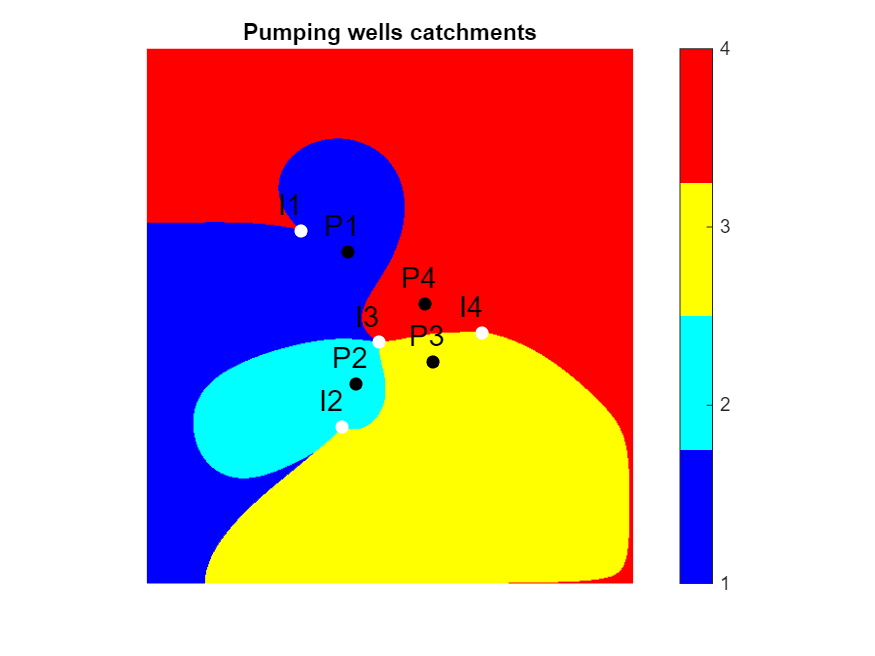

figure;                                     % new figure 
colormap(jet(4));                           % colormap made from 4 colors
plotCellData(G2D, pump_well_index, ...      % plot grid cell well catchment indices
    'DataType', 'Index',...
    'EdgeColor', 'none');                   %    hiding the grid edges
axis tight equal off;                       % hide axes and set aspect ratio to 1
title('Pumping wells catchments');          % add title 
hold on; 
scatter(xinj,yinj,40,'w','filled');         % mark injectors with white dots
scatter(xpmp,ypmp,40,'k','filled');         % mark producers with black dots
text([xinj,xpmp]-500, [yinj,ypmp]+500, ...  % show labels of all wells
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, ... 
    'FontSize',14);
hold off;

The plot clearly illustrates the aquifer partitions formed by the catchments of the four pumping wells. It appears that P4 has the largest catchment area, followed by P3, P1, and finally P2. This outcome is expected, as P2 is associated with a lower pumping flow rate and is situated between two injection wells (I2 and I3) at relatively short distances. 

To quantitatively confirm these results, we will create a pie chart illustrating the percentage of each pumping well catchment relative to the total aquifer pore volume. 

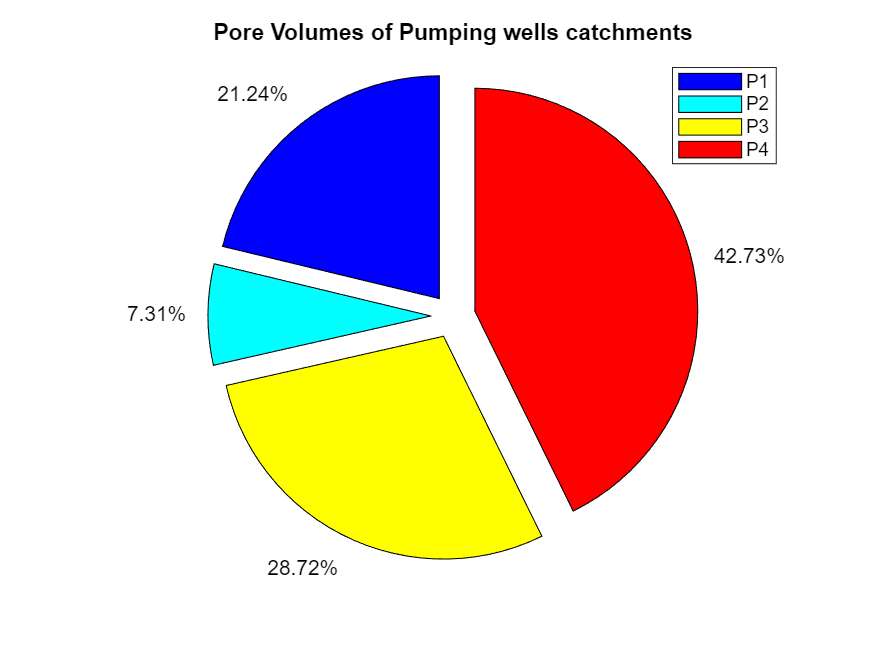

figure;                                             % new figure 
colormap(jet(4));                                   % colormap made from 4 colors
pie(pump_well_volume,ones(4,1),'%.2f%%');           % plot a pie of pore volumes of catchments
labels = {'P1','P2','P3','P4'};                     % labels for the legend
legend(labels, 'Location','best');                  % add legend to the plot
title('Pore Volumes of Pumping wells catchments');  % add title 

Thus, the previously established ranking of the pumping well catchments is confirmed. The catchment of well P4 comprises more than 40% of the aquifer, while well P2 accounts for only around 7%. The remaining wells approximately share the remaining volume of the aquifer. 

## Simulate Injection Wells Catchments

To simulate the catchments of the injection wells, we solve similar steady-state advection equations as we did for the pumping wells, but in the forward direction. This involves reversing the sign in front of the velocity field in the equations. The function `injectionCatchments` performs this task and returns an array that maps each grid cell to the index of its corresponding injection well catchment. 


tic
[inj_well_index,inj_well_volume,~] = injectionCatchments(Grid, V, W);

iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 0.5 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations


toc

Elapsed time is 3.799793 seconds.


## Visualize Catchments of Injection Wells 

We follow the same steps used earlier to visualize the catchments of the pumping wells, but this time using the grid cell well catchment indices for the injection wells. 

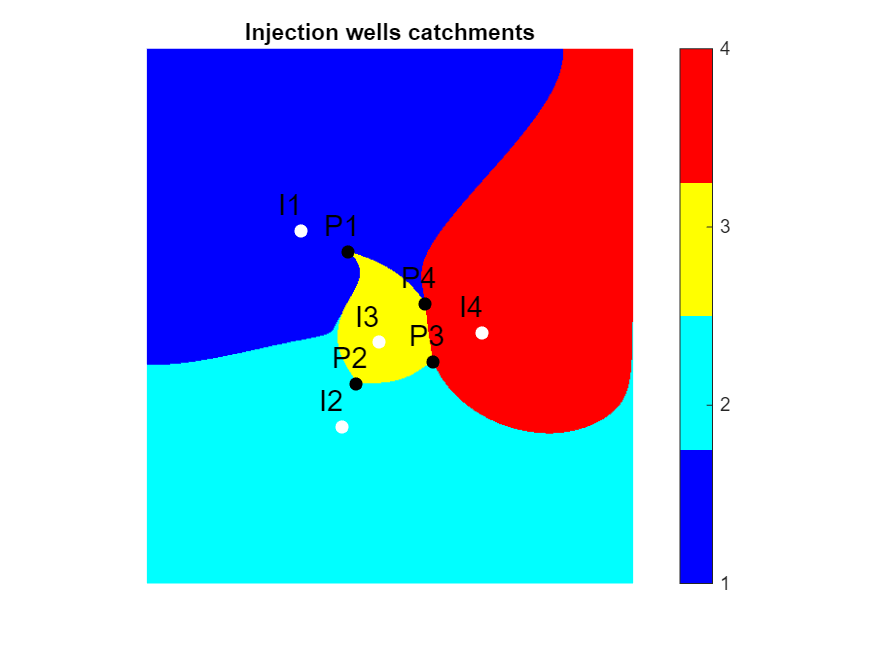

figure;                                     % new figure 
colormap(jet(4));                           % colormap made from 4 colors
plotCellData(G2D, inj_well_index, ...       % plot grid cell well catchment indices
    'DataType', 'Index',...
    'EdgeColor', 'none');                   %    hiding the grid edges
axis tight equal off;                       % hide axes and set aspect ratio to 1
title('Injection wells catchments');        % add title 
hold on; 
scatter(xinj,yinj,40,'w','filled');         % mark injectors with white dots
scatter(xpmp,ypmp,40,'k','filled');         % mark producers with black dots
text([xinj,xpmp]-500, [yinj,ypmp]+500, ...  % show labels of all wells
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, ...
    'FontSize',14);
hold off;

Similarly, we will now plot the contribution of each injection well catchment to the total pore volume of the aquifer.

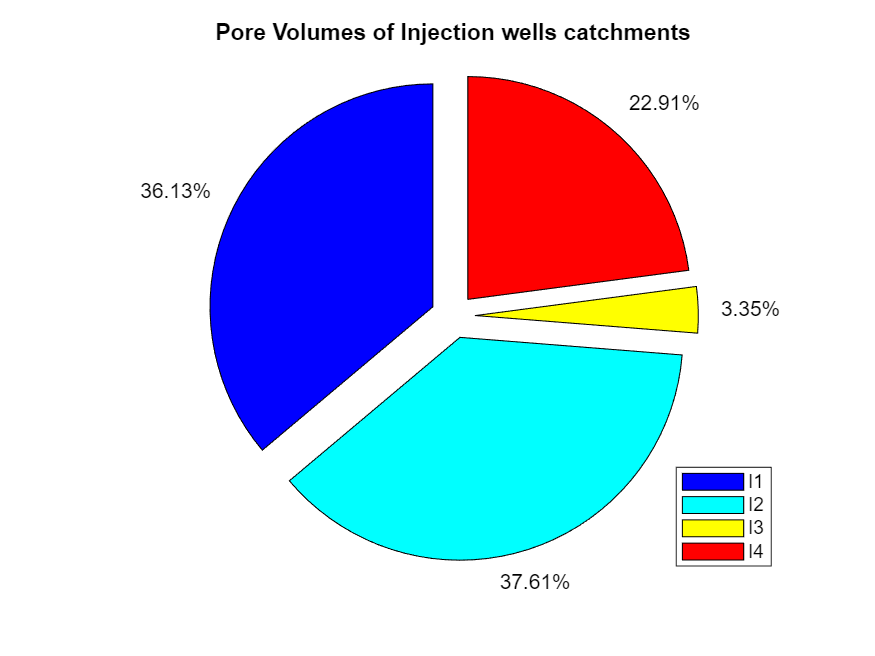

figure;                                             % new figure 
colormap(jet(4));                                   % colormap made from 4 colors
pie(inj_well_volume,ones(4,1),'%.2f%%');            % plot a pie of pore volumes of catchments
labels = {'I1','I2','I3','I4'};                     % labels for the legend
legend(labels, 'Location','best');                  % add legend to the plot
title('Pore Volumes of Injection wells catchments');% add title 

The catchments of wells I2 and I1 are the most significant, followed by I4, while the catchment of I3 is minor due to its location, as it is surrounded by the four pumping wells on all sides.

## Visualize Catchments of Pumping-injection Well Pairs

Once the spatial extents of the injection and pumping well catchments are determined, it becomes possible to calculate all potential catchments intercepted by pairs of injection and pumping wells. This is accomplished using the function `wellPairCatchments`, which returns an m-by-2 string array of all interacting well pairs (each string begins with 'I' or 'P' to denote an injection or production well, followed by the well number). The next returned argument is the index of the intercepted well-pair partition for each model grid cell, providing spatial partitions that indicate how the injection and production wells are connected. Finally, an m-by-1 array is returned, containing the calculated aquifer pore volume for each well-pair partition. 

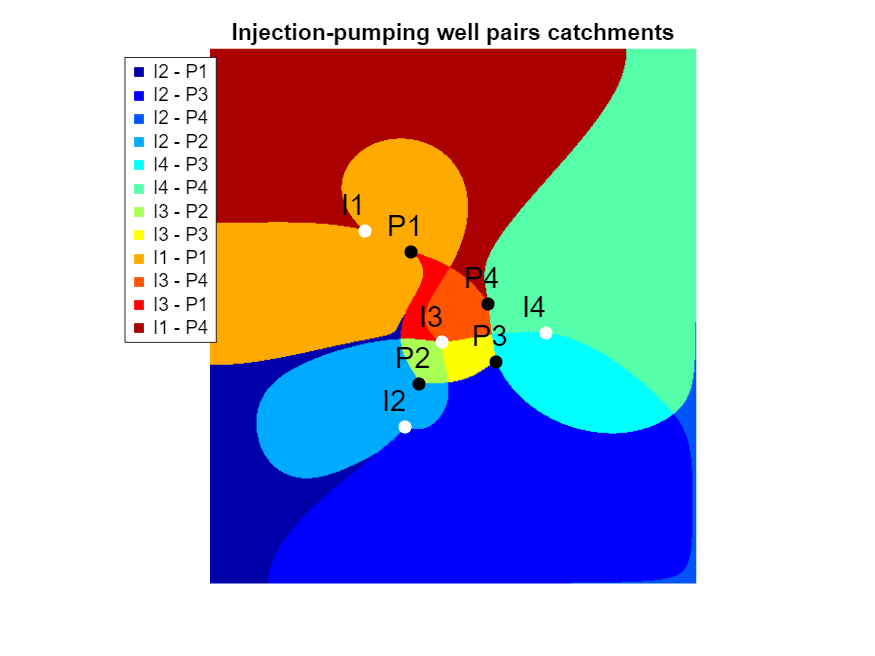

[well_pair,well_pair_index,well_pair_volume] = wellPairCatchments(Grid, inj_well_index, pump_well_index); 
figure;
colormap(jet(size(well_pair,1)));
colors = colormap;  % Get the color map values
plotCellData(G2D, well_pair_index, ... 
    'EdgeColor','none', 'HandleVisibility', 'off');
colorbar off; 
axis tight equal off; 
title('Injection-pumping well pairs catchments'); 
hold on; 
scatter(xinj,yinj,40,'w','filled', 'HandleVisibility', 'off');
scatter(xpmp,ypmp,40,'k','filled', 'HandleVisibility', 'off');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
legendEntries = strings(size(well_pair, 1), 1);
for i = 1:size(well_pair, 1)
    legendEntries(i) = well_pair(i, 1) + " - " + well_pair(i, 2);  % Combine 'I1 - P3' for instance
end
% Now create dummy lines to represent each legend entry
Np = size(well_pair, 1);  % Number of well pairs
dummyPatches = gobjects(Np, 1);  % Preallocate array for dummy handles
for i = 1:Np
    % Create invisible patches for the legend, using the correct colors
    dummyPatches(i) = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(i,:), ...
        'MarkerEdgeColor', 'none', 'DisplayName', legendEntries(i));  % Filled squares with correct color
end
legend(gca, legendEntries, 'Location','Best');
hold off;

Now, we will plot a horizontal bar chart to illustrate the contribution of pumping wells to the catchments of the injection wells. Each bar will represent the percentage of aquifer pore volume that an injection well shares with a corresponding pumping well. Notably, the colors of the bar segments correspond to those used to represent the spatial extents of the well-pair catchments. Each bar segment indicates the percentage volumetric contribution of the corresponding pumping well catchment to the injection well catchment.  

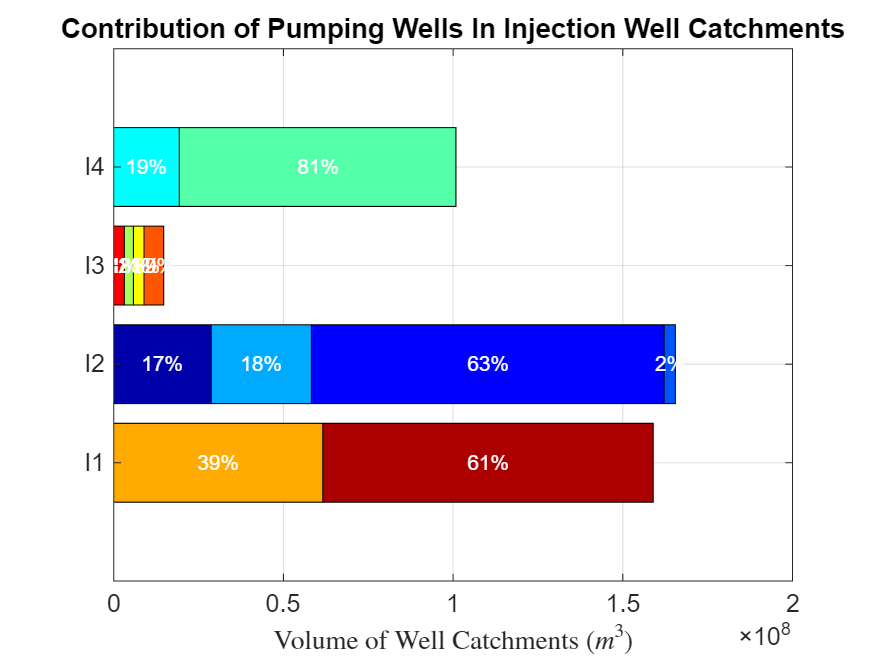

[hfig,~] = plotInjectionCatchmentPartitions(well_pair, well_pair_volume, colors, {'I1', 'I2', 'I3', 'I4'}, {'P1', 'P2', 'P3', 'P4'});
ax = findall(hfig, 'Type', 'axes');
title('Contribution of Pumping Wells In Injection Well Catchments');
xlabel('Volume of Well Catchments ($m^3$)', 'Interpreter', 'latex');
set(ax, 'FontSize', 12);

Similarly, to plot the relative contributions of injection wells to the catchments of pumping wells, we can reuse the `plotInjectionCatchmentPartitions` function without the need to create a new one. We only need to swap the two columns of the `well_pair` variable and swap the names of the injection and production wells used as arguments. 

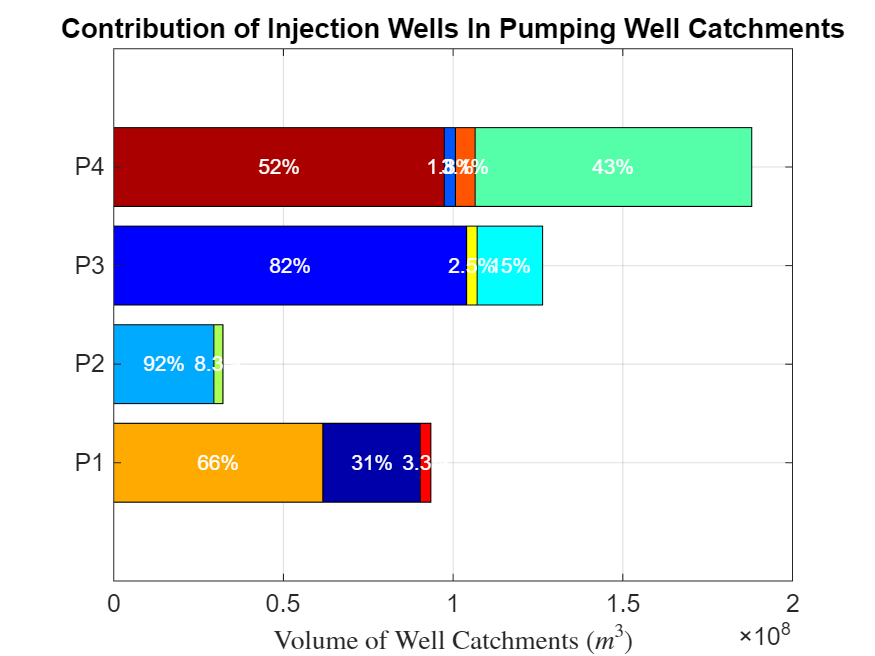

% Swap the first and second columns
swap_well_pair(:, [1, 2]) = well_pair(:, [2, 1]);
[hfig,~] = plotInjectionCatchmentPartitions(swap_well_pair, well_pair_volume, colors, {'P1', 'P2', 'P3', 'P4'}, {'I1', 'I2', 'I3', 'I4'});
ax = findall(hfig, 'Type', 'axes');
title('Contribution of Injection Wells In Pumping Well Catchments');
xlabel('Volume of Well Catchments ($m^3$)', 'Interpreter', 'latex');
set(ax, 'FontSize', 12);

Based on the recent analyses of the well-pair catchments, we can conclude that such analyses are virtually impossible using particle tracking methods. In contrast, the Double Delineation Approach (DDA) facilitates this level of insight, allowing us to effectively assess the interactions and contributions of injection and pumping wells.

## Travel Times Simulations 

We simulate forward and backward travel times sequentially to obtain the residence time as their sum.  

tic
ftt = travelTime(Grid, V, W, true);
btt = travelTime(Grid, V, W, false);
residence_time = ftt + btt;
toc

Elapsed time is 0.318913 seconds.


As we can conclude, the response is nearly instantaneous, even when considering a large grid with more than a quarter of a million cells. 

## Travel Times Visualization 

The following three figures present the results of these simulations. The first and second figures display filled iso-contours of forward and backward travel times at 10-year intervals, respectively. The last figure illustrates only the iso-values at the same time levels. 

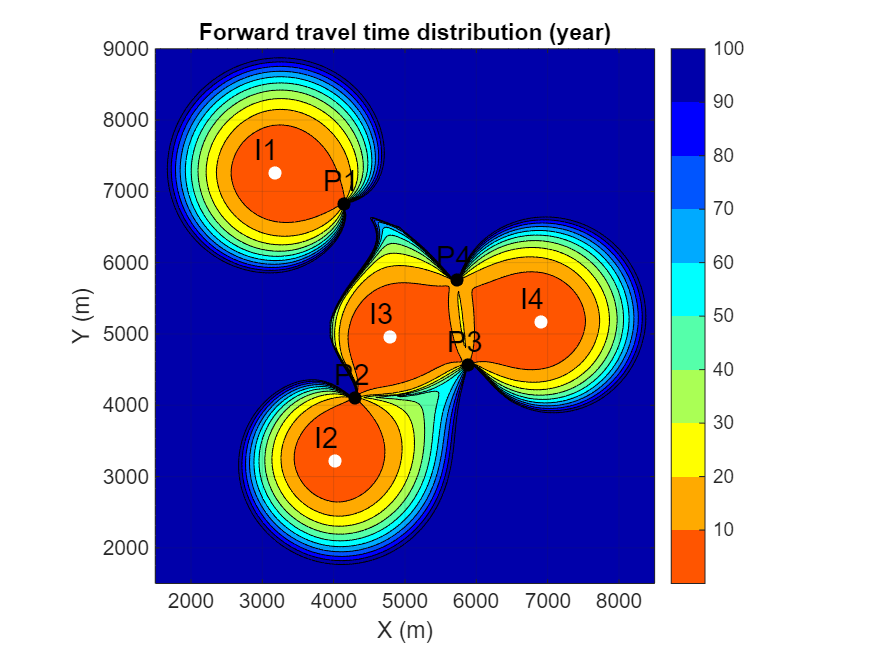

figure; 
colormap(flipud(jet(10)));
opt.fill = 'on';
plotContourData(G2D,ftt/year,opt,'LevelList',0:10:100);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Forward travel time distribution (year)'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

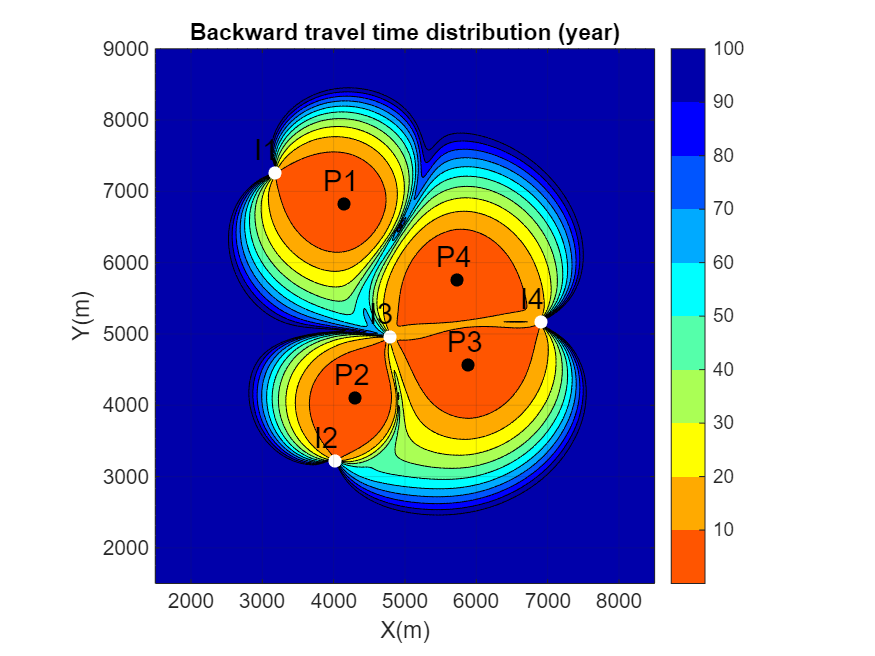

figure; 
colormap(flipud(jet(10)));
opt.fill = 'on';
plotContourData(G2D,btt/year,opt,'LevelList',0:10:100);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Backward travel time distribution (year)'); 
xlabel('X(m)'); ylabel('Y(m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

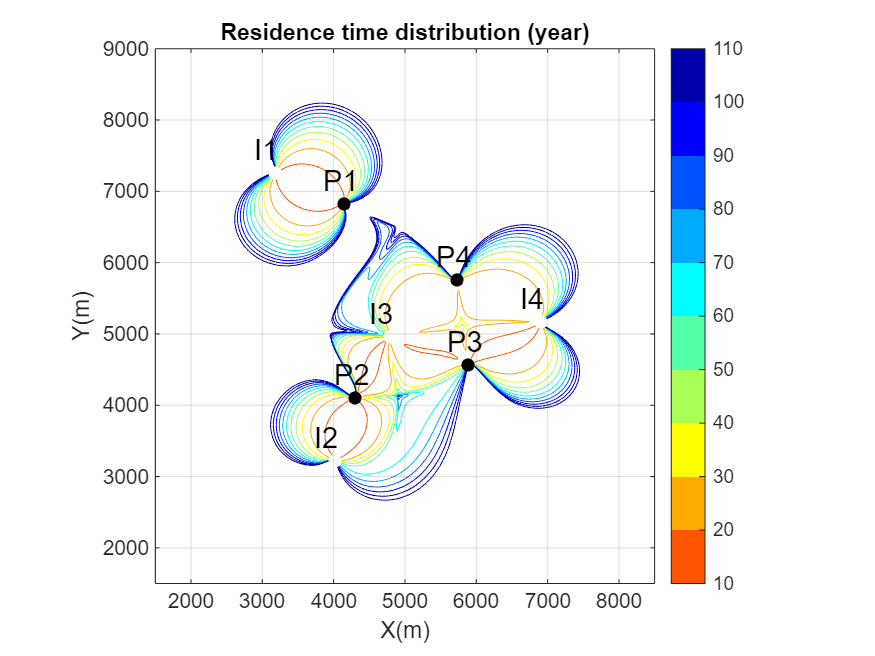

figure; 
colormap(flipud(jet(10)));
opt.fill = 'off';
plotContourData(G2D,residence_time/year,opt,'LevelList',10:10:110);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Residence time distribution (year)'); 
xlabel('X(m)'); ylabel('Y(m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

These results indicate that the I1-P1 doublet remains isolated from the others, even over the long term. However, hydraulic interference may occur if production is sustained for extended periods.  

Using the Double Delineation Approach (DDA) simplifies the process of identifying capture zones at specific times, making it more straightforward. This is because we are dealing with a continuously calculated variable that is simulated across every grid cell of the model, allowing for easier post-processing and querying at any position. In contrast, the particle tracking method calculates travel times only at specific points along the traced flow paths, which are highly dependent on the initial positions of the particles. As a result, interpolating travel times derived from the particle tracking method often leads to inaccuracies. 

## Visualizing Time Related Capture Zones

Finally, to illustrate the relationships between well catchments and travel times in determining time-related capture zones, we will plot the well catchments overlaid by isochrones at specific time intervals.

Let’s begin with the catchments of the injection wells and the isochrones of the forward travel time:

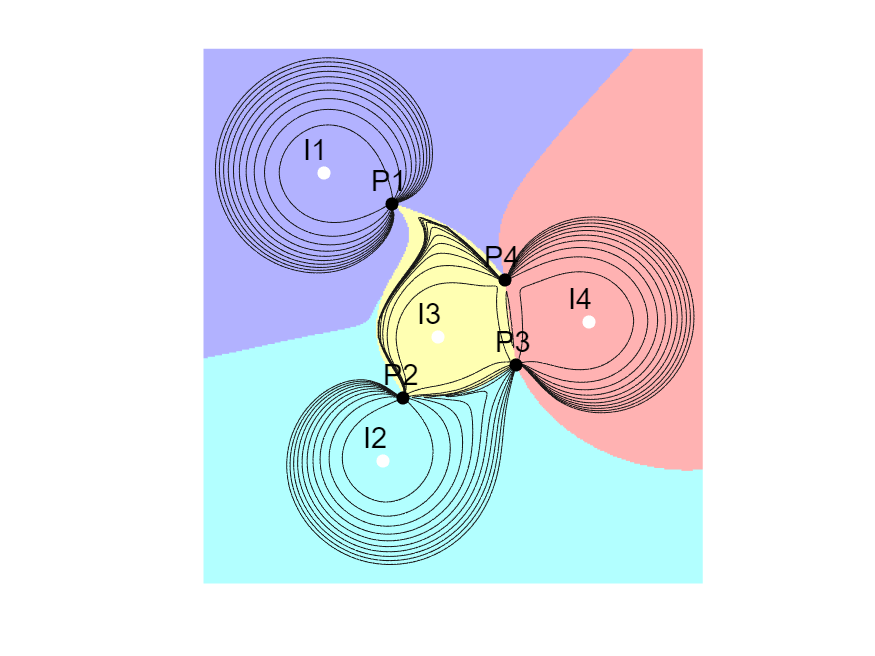

figure;
colormap(jet(4));
plotCellData(G2D,inj_well_index,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,ftt/year,opt,'LevelList',0:10:100);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

Next, we will examine the catchments of the production wells alongside the isochrones of the backward travel time:

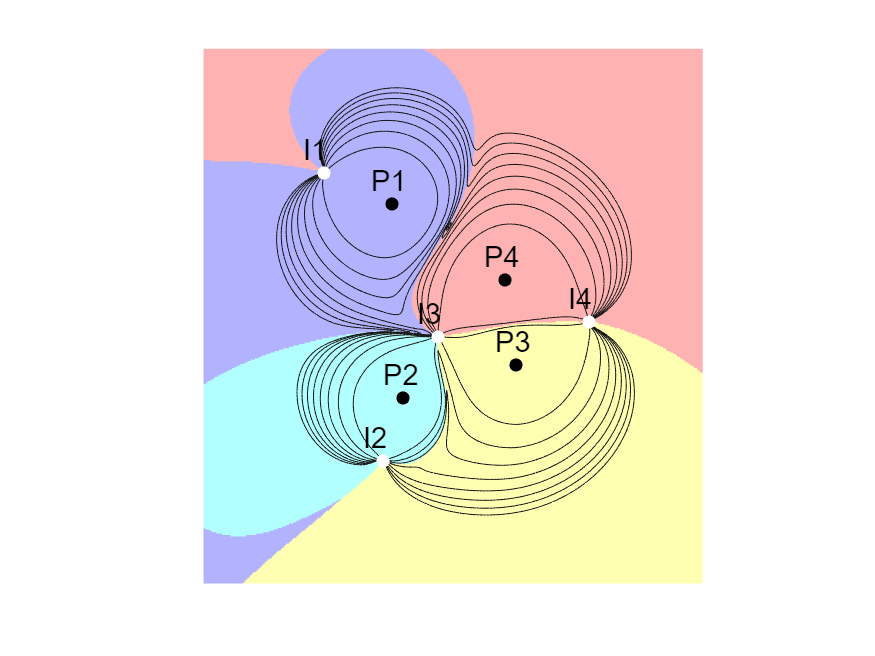

figure;
colormap(jet(4));
plotCellData(G2D,pump_well_index,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,btt/year,opt,'LevelList',0:12.5:100);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

This will be followed by the catchments of the injection-production well pairs and the isochrones of the residence time:

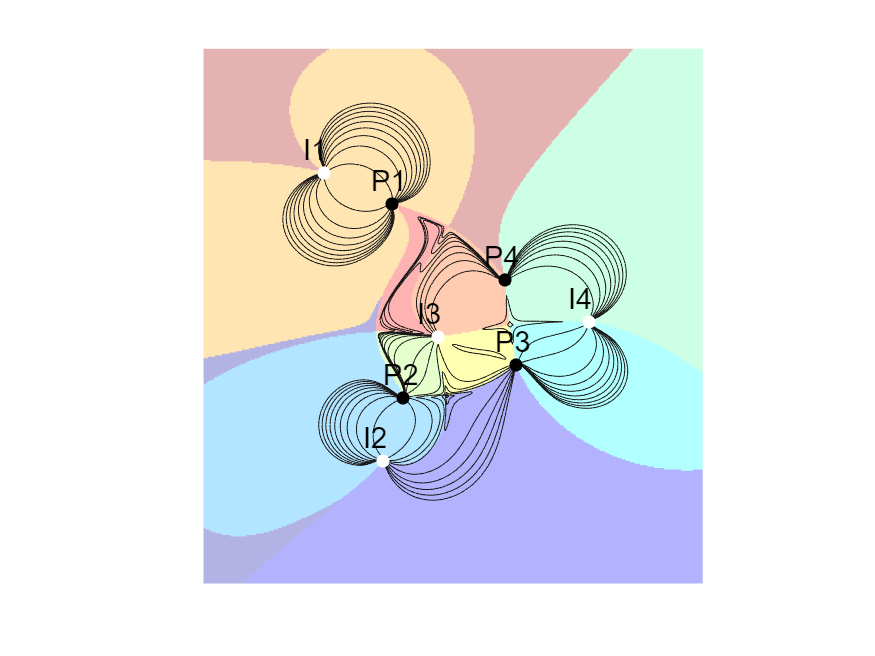

figure;
colormap(jet(size(well_pair,1)));
plotCellData(G2D,well_pair_index,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,residence_time/year,opt,'LevelList',10:12.5:110);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);

We observe that in all cases, the time-related capture zones for a given injection well, pumping well, or pair of wells—delimited by isochrones—are always located within the catchment of that well or within the well-pair catchment. 

## Discussion

The results of our simulations demonstrate the efficacy of the Double Delineation Approach (DDA) in analyzing the interactions between injection and pumping wells within a geothermal reservoir. Our findings indicate that the spatial extents of well catchments can be effectively identified, allowing for a comprehensive understanding of hydraulic relationships that are often obscured when using traditional methods like particle tracking.

The analysis revealed that the I1-P1 doublet remains isolated from others even over extended periods. This isolation suggests that specific operational strategies could be implemented to manage production without significant hydraulic interference, thereby enhancing the efficiency of resource extraction.

The DDA enables the continuous calculation of variables across every grid cell, facilitating straightforward post-processing and querying. In contrast, the particle tracking method limits travel time calculations to specific points along flow paths, leading to inaccuracies when interpolating travel times. This distinction underscores the advantages of DDA in capturing time-related dynamics within the aquifer system.

Our investigation into time-related capture zones further illustrated that these zones, defined by isochrones, consistently reside within the corresponding well catchments. This finding reinforces the reliability of using isochrones for assessing the temporal aspects of groundwater capture in the context of injection and pumping operations.

In summary, the DDA not only enhances our understanding of well catchment dynamics but also offers a robust framework for future studies aimed at optimizing geothermal resource management. Further research could explore the implications of these findings on long-term sustainability and operational efficiency within geothermal reservoirs.

In this example, we were able to address two of the questions posed earlier using the Double Delineation Approach (DDA). The third question, which involves partitioning the flow rate between injection and production wells—an extension introduced in [[3](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)]—will be showcased in the next example. 

To proceed with the next example, save all variables in the current workspace to a file named `example4.mat` by using the `save` function without specifying any variable names. This will store all current workspace variables in the `.mat` file.

save('example4.mat');

## References 

[1] [Sbai, M.A. (2018). A Practical Grid-Based Alternative Method to Advective Particle Tracking. Groundwater, 56(6), 881-892. https://doi.org/10.1111/gwat.12646](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)

[2] [Frind, E.O., D.L. Mohammad, and J.W. Molson (2002). Delineation of three-dimensional well capture zones for complex multi-aquifer systems. Groundwater, 40(6), 586-598. https://doi.org/10.1111/j.1745-6584.2002.tb02545.x](https://doi.org/10.1111/j.1745-6584.2002.tb02545.x)

[3] [Sbai, M.A. (2020); A Dual Delineation Approach to Untangle Interferences in Well Doublets Systems. Groundwater, 58(5), 822-830. http://dx.doi.org/10.1111/gwat.12978](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)

Author: M.A. Sbai, Ph.D.

Copyright (C) 2024 Mohammed Adil Sbai

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.